Playing head_m.wav at 24000 Hz with duration 0.26 seconds and 6249 samples


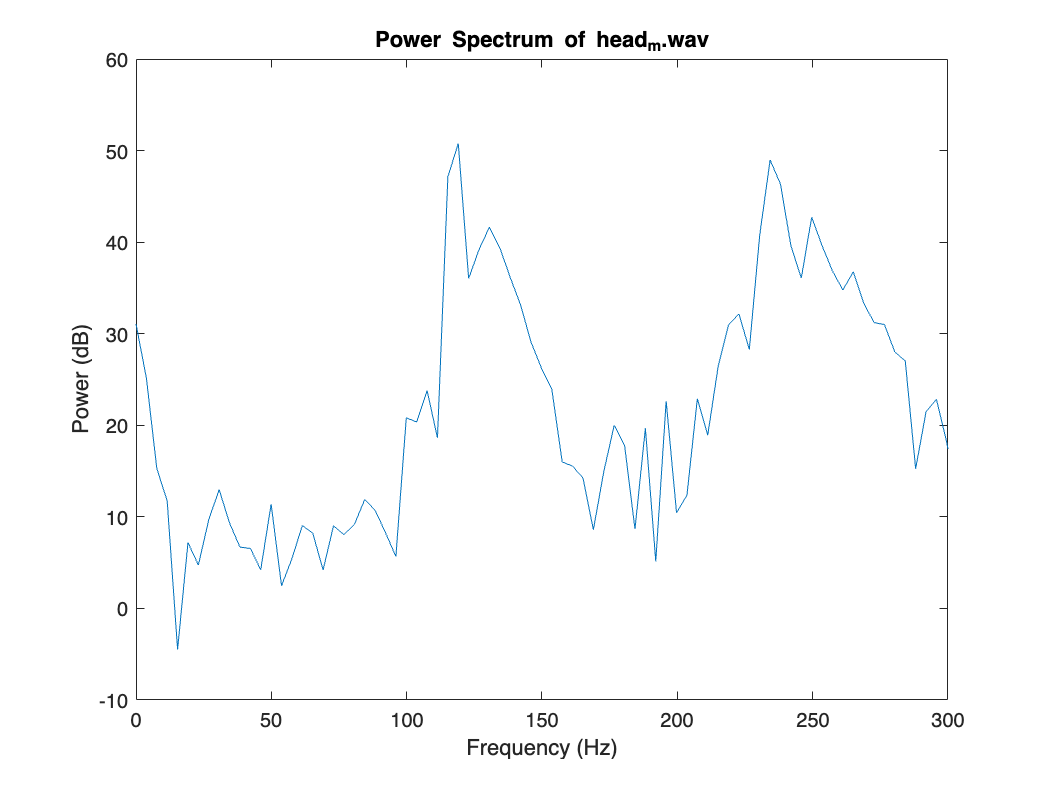

file_1 = 'head_f.wav';
[audio, fs, duration, numSamples] = playAudio(file_1);

Window Size: 480 samples (20.00 ms)
Overlap: 360 samples (15.00 ms)
FFT Length (N): 2048

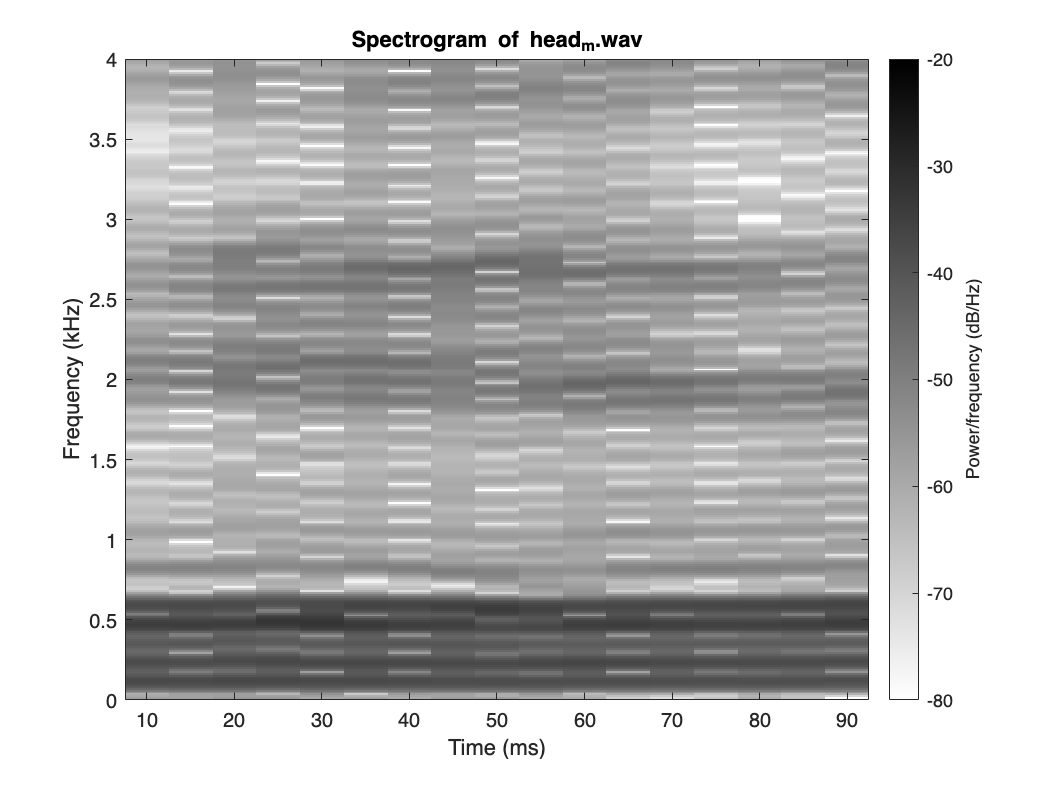

% select a 100ms quasi-stationary segment
segmentDuration = 0.1;
segment = extractCenterSegment(audio, fs, segmentDuration, file_1);
plotSpectrogram(segment, fs, file_1);

LPC Gain Factor: 0.0304


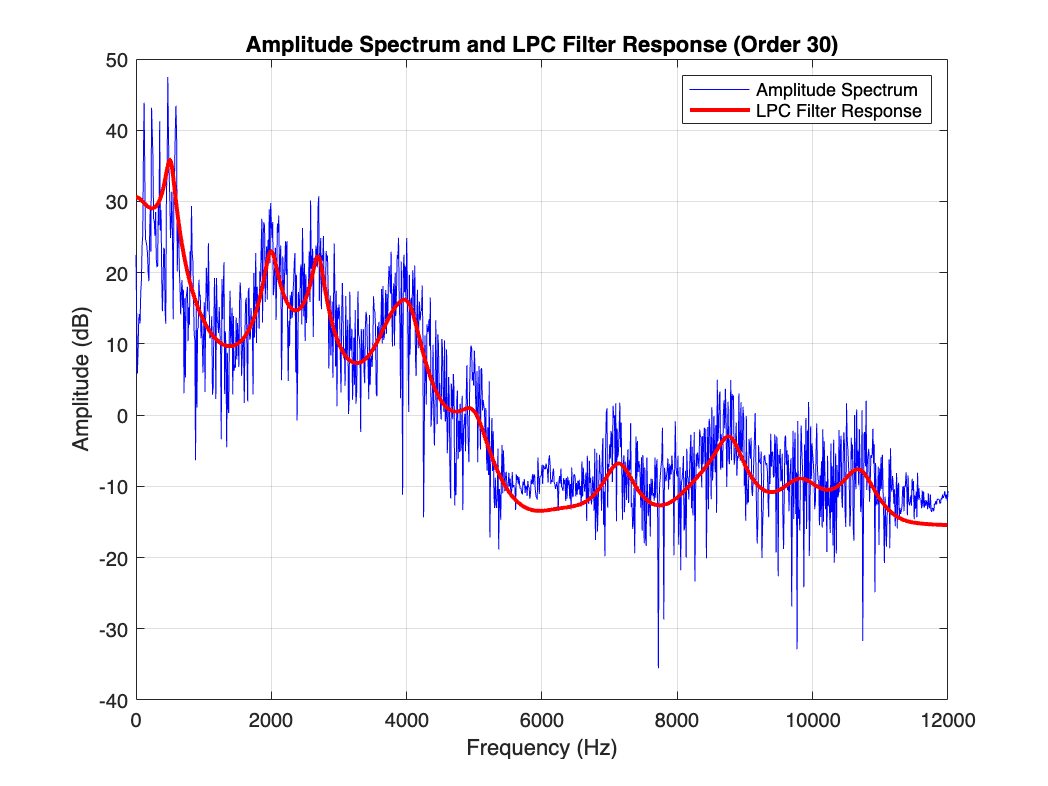

lpcOrder = 30;
plotLPCResponse(segment, fs, lpcOrder);

[formants] = estimateFormants(segment, fs, lpcOrder);

Estimated Formant Frequencies (Hz):
F1: 508.27 Hz
F2: 1051.41 Hz
F3: 1993.93 Hz


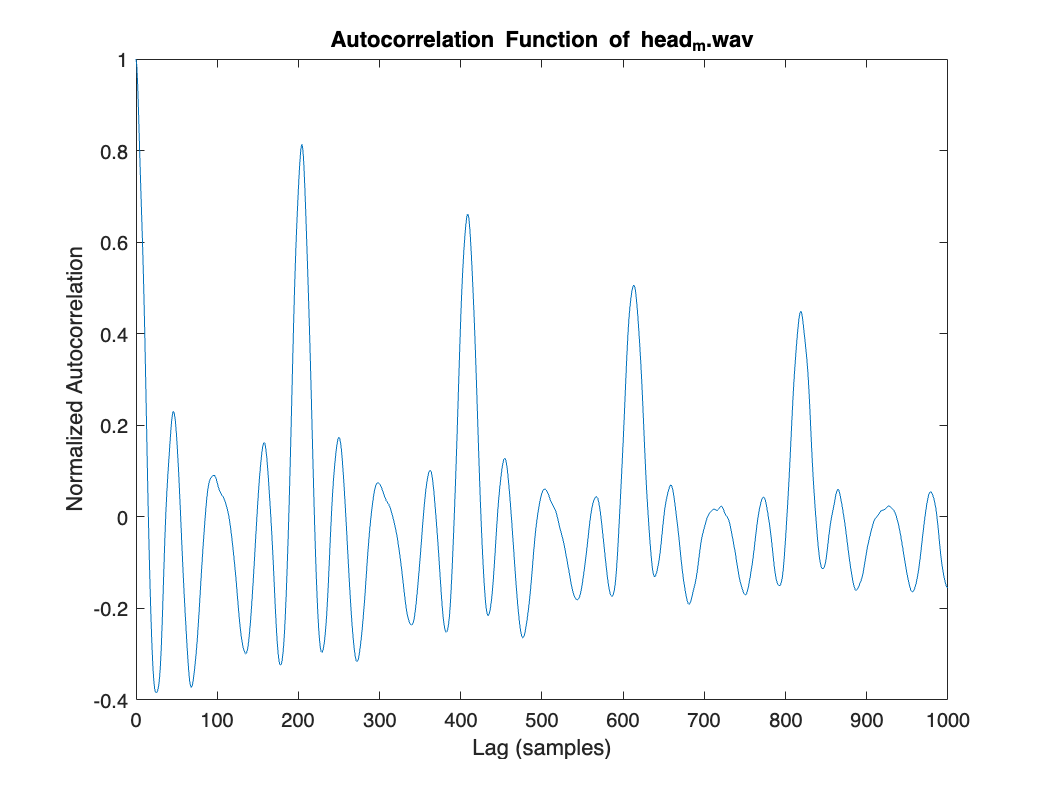

Estimated F0 using autocorrelation: 117.65 Hz


f0_estimate = estimateF0ByAutoCorrelation(segment, fs, file_1);

f0_power = estimateF0ByPowerSpectrum(segment, fs);

Estimated F0 using power spectrum: 120.00 Hz


f0 = mean(pitch(segment, fs));
fprintf('Estimated F0 using pitch function: %.2f Hz\n', f0);

Estimated F0 using pitch function: 117.19 Hz


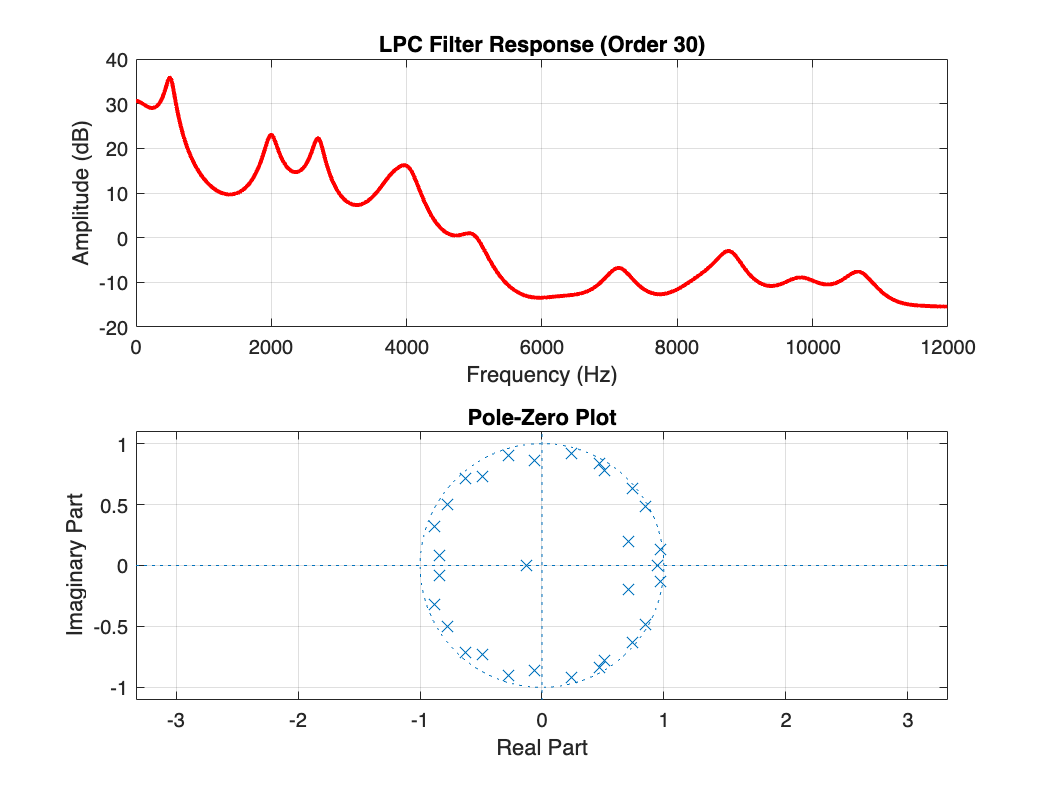

plotLPCPoleZero(segment, fs, lpcOrder);

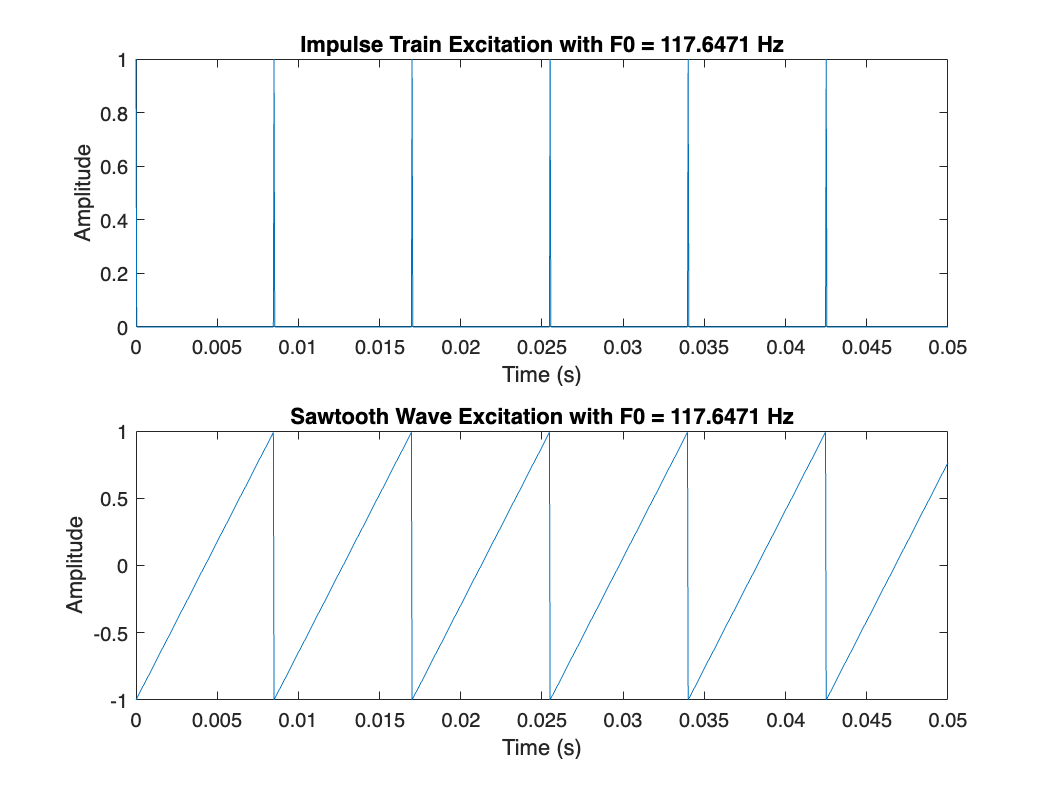

[synthesizedImpulse, synthesizedSawtooth] = synthesizeLPC(segment, fs, f0_estimate, lpcOrder, 1, file_1);

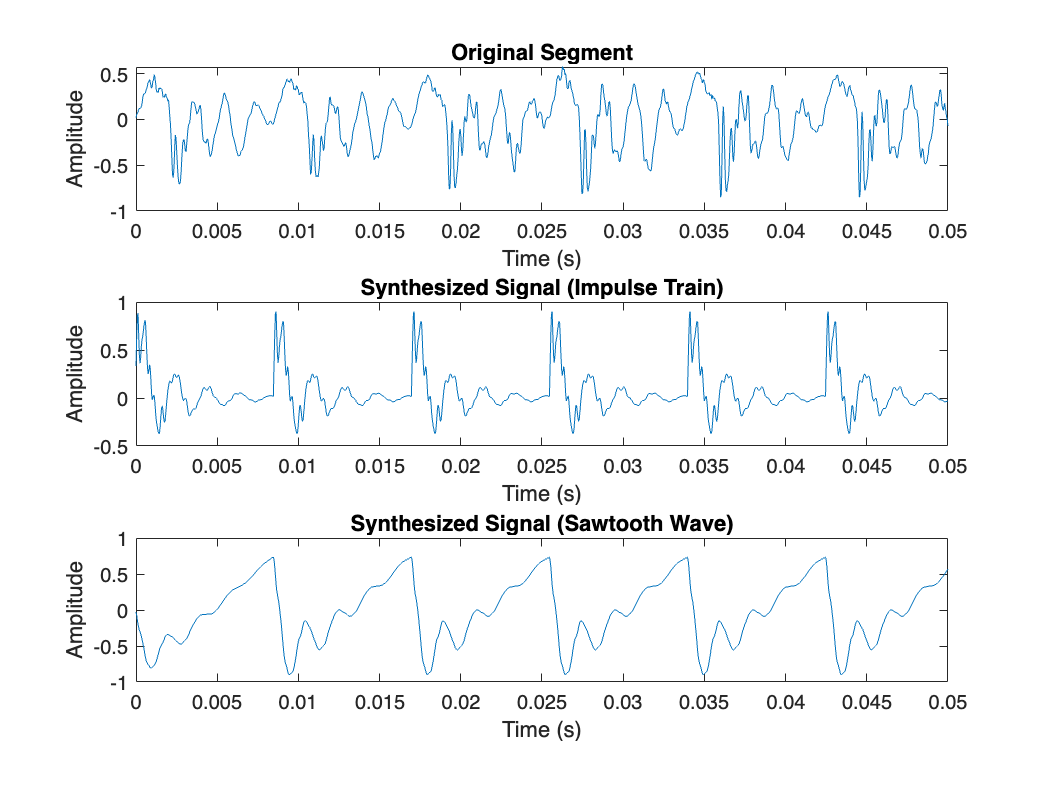

plotSynthesis(segment, fs, synthesizedImpulse, synthesizedSawtooth);

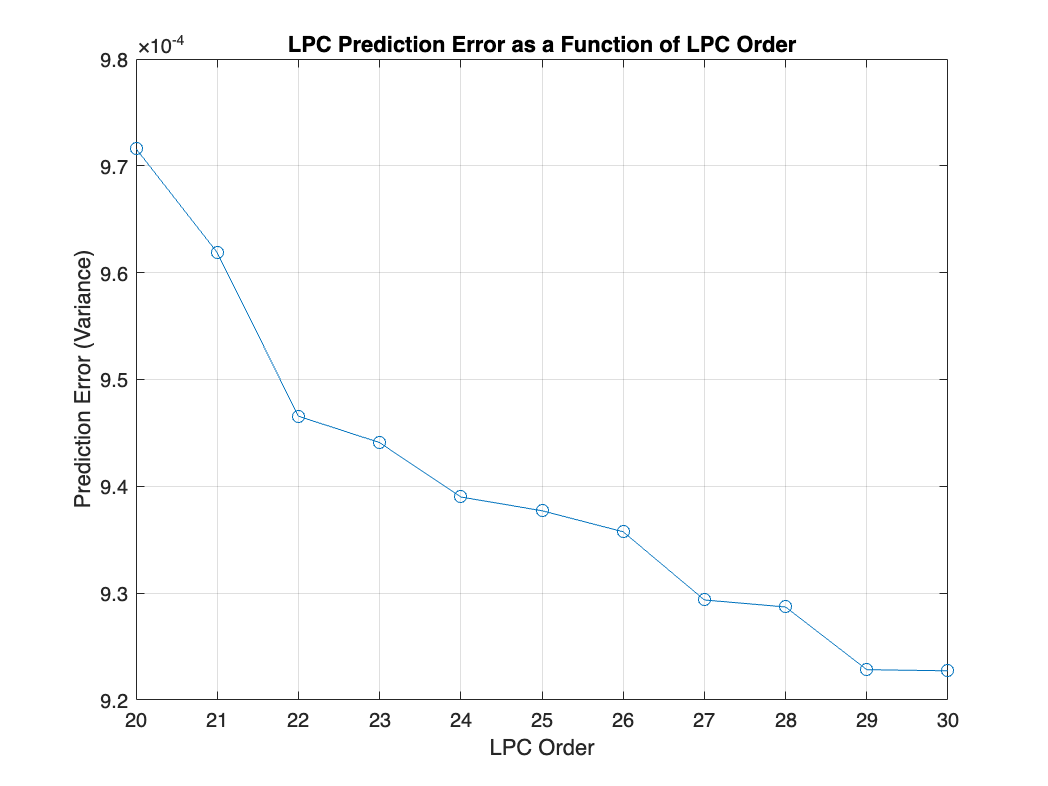

orderAnalysis(segment, 20, 30)

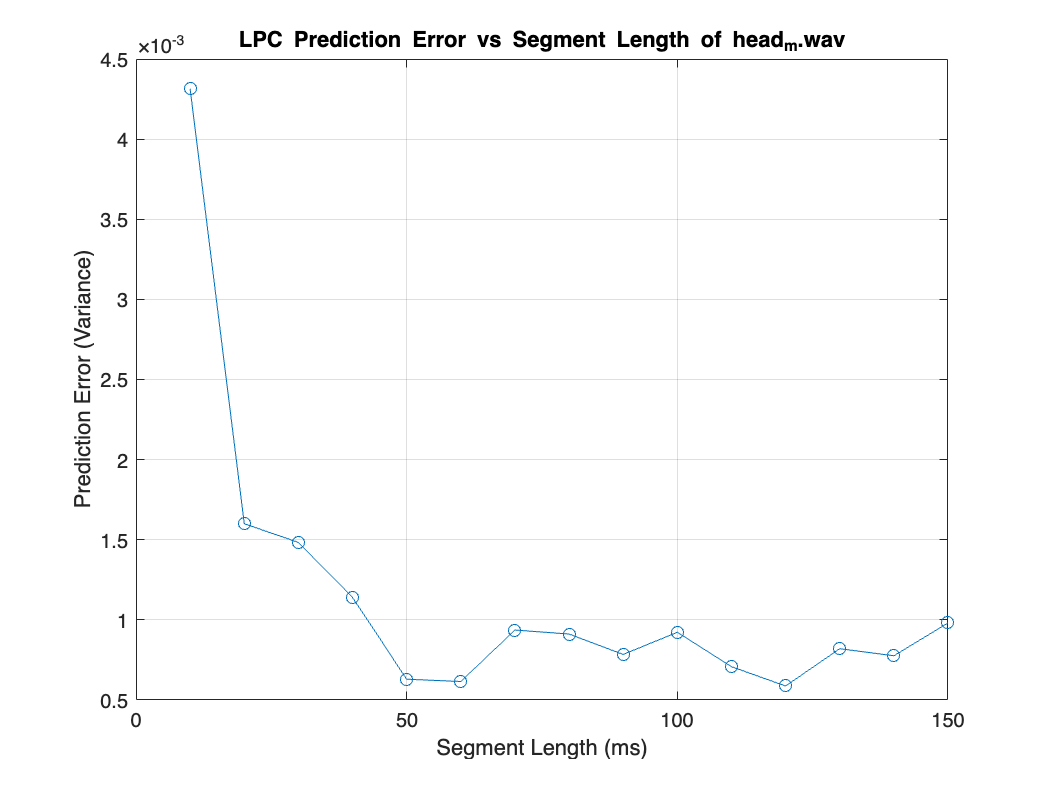

segmentAnalysis(audio, fs, 30, file_1)

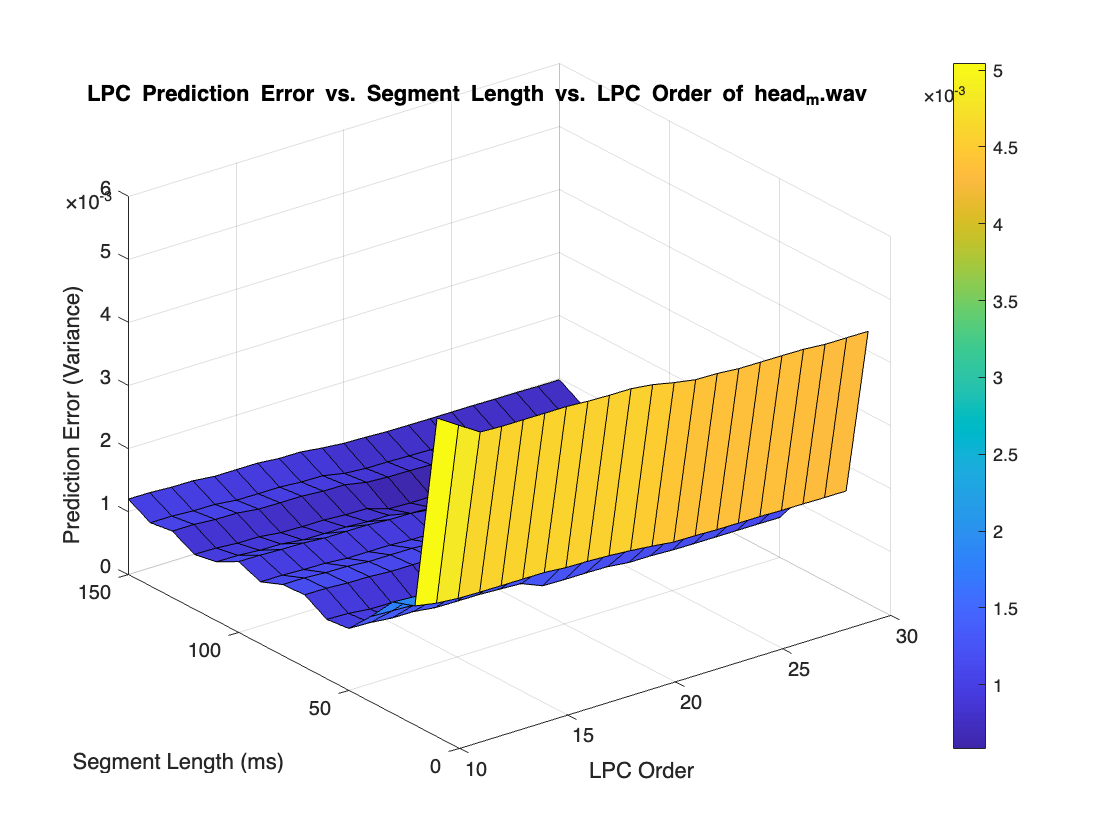

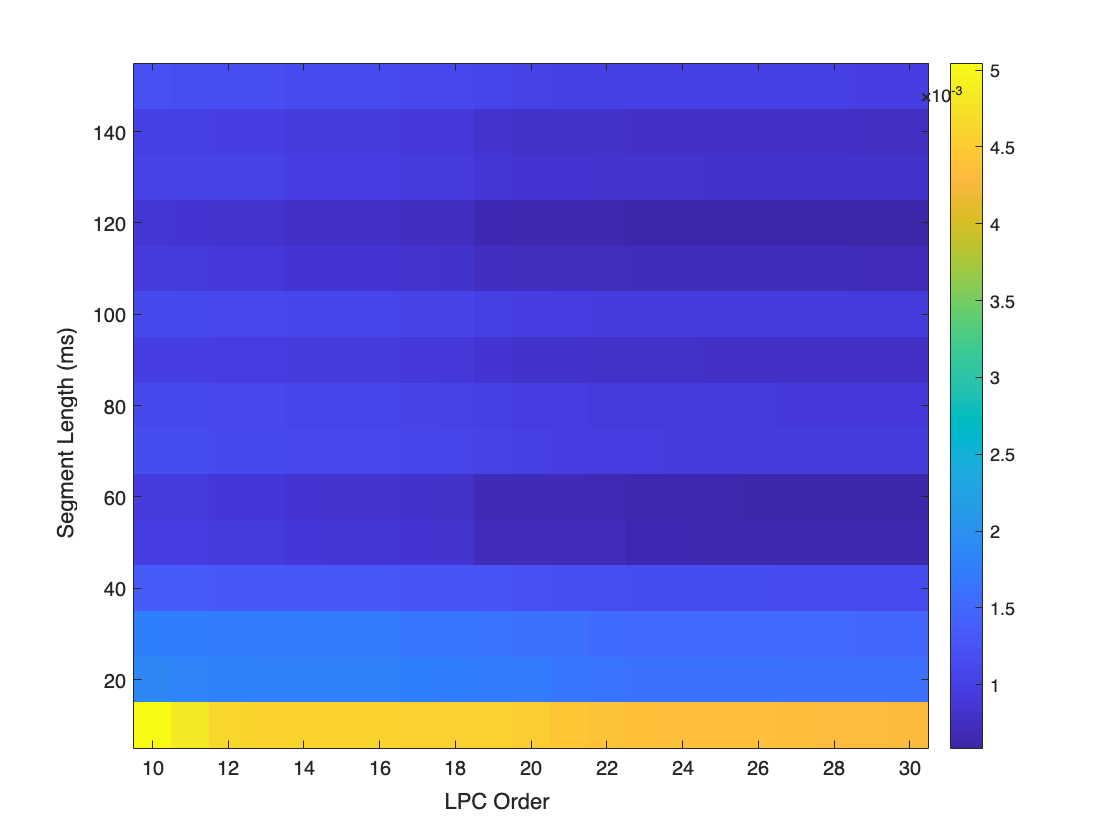

orderSegmentAnalysis(audio, fs, file_1)